# Manipulation Estimation and Controls: Assignment 1

Submitted by: Sushanth Jayanth

## Q1. 

**Linear system is defined with in the form x = Ax + Bu**

Where A and B are defined as

A = [[0,1,0];[0,0,1];[1,5,7]];
B = transpose([1,0,0]);
C = [0,1,3];

####  1 a. Stability Criterion for the above system is defined by the eigenvalues of A

eigen_A = eig(A)

eigen_A =    7.6690 + 0.0000i
  -0.3345 + 0.1361i
  -0.3345 - 0.1361i


    Since one of the eigen values is positive, the linear system A is unstable

####   1  b. Controllability of the system

Q = ctrb(A,B)

Q =      1     0     0
     0     0     1
     0     1     7


clear rank
rank_of_Q = rank(Q)

rank_of_Q = 3

  Matrix Q is of rank n (same rank as of A). Therefore the system is controllable

####  1  c. Initial State Vector is given as: 

 The output of the unforced system plotted below:

x_0 = [0;1;0]

x_0 =      0
     1
     0


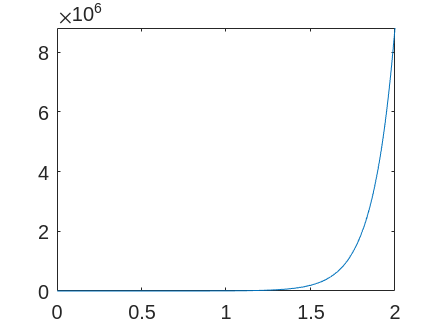


syms t
fplot(C*expm(A*t)*x_0, [0,2])

####  1  d. Find the feedback gain K to make the system stable

eig_values = [-1 + 1i, -1 - 1i, -2]

eig_values =   -1.0000 + 1.0000i  -1.0000 - 1.0000i  -2.0000 + 0.0000i


K = place(A,B,eig_values)

K =    11.0000   60.0000   88.0000


####    1 e. Plot output of the system after control input

new_mat = A-B*K

new_mat =   -11.0000  -59.0000  -88.0000
         0         0    1.0000
    1.0000    5.0000    7.0000


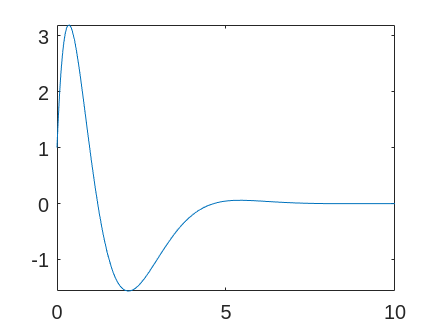

fplot(C*expm(new_mat*t)*x_0, [0,10])

## Q 2. 

#### **"Pendulum on a cart" system**

#### 2 a. Cart pendulum equations as non-linear state-space equations

Cart pendulum equations are written as shown below:

syms F
syms z
F = gamma*xc_ddot - beta*phi_ddot*cos(phi) + beta*phi_dot*phi_dot*sin(phi) + mu*xc_dot % = F

$$F = \beta \,\sin\left(\varphi \right)\,{\dot{\varphi }}^{2}+\gamma \,\ddot{\mathrm{xc}}+\mu \,\dot{\mathrm{xc}}-\beta \,\ddot{\varphi }\,\cos\left(\varphi \right)$$


z = 0

z = 0

z = alpha*phi_ddot - beta*xc_ddot*cos(phi) - D*sin(phi)

$$z = \alpha \,\ddot{\varphi }-\text{D}\,\sin\left(\varphi \right)-\beta \,\ddot{\mathrm{xc}}\,\cos\left(\varphi \right)$$

The state vector x is given as:

syms xc_ddot xc_dot xc gamma beta phi phi_dot phi_ddot mu alpha D u 
x = [xc; phi; xc_dot; phi_dot]

$$x = \left(\begin{array}{c} \mathrm{xc}\\ \varphi \\ \dot{\mathrm{xc}}\\ \dot{\varphi } \end{array}\right)$$

The standard mechanical form is given as:

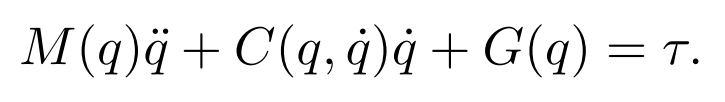

The state-space representation of the standard mechanical form is given as:

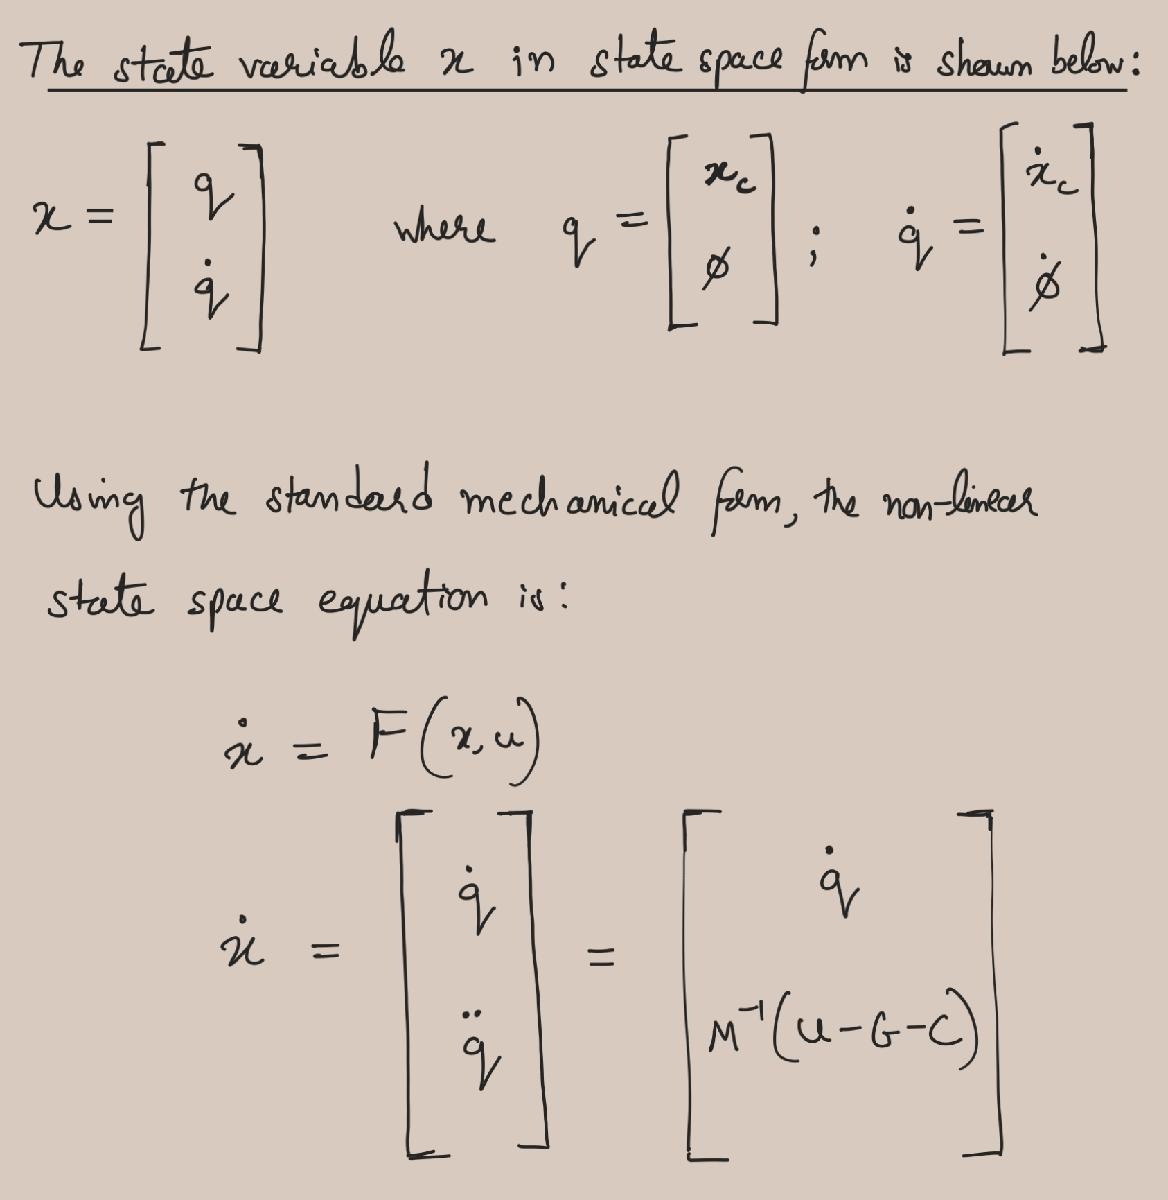

The derivation of the above equation is shown below:

syms xc_ddot xc_dot xc gamma beta phi phi_dot phi_ddot mu alpha D u 

M = [[gamma, -beta*cos(phi)];[-beta*cos(phi),alpha]]

$$M = \left(\begin{array}{cc} \gamma & -\beta \,\cos\left(\varphi \right)\\ -\beta \,\cos\left(\varphi \right) & \alpha \end{array}\right)$$

C = [beta*phi_dot*phi_dot*sin(phi) + mu*xc_dot; 0]

$$C = \left(\begin{array}{c} \beta \,\sin\left(\varphi \right)\,{\dot{\varphi }}^{2}+\mu \,\dot{\mathrm{xc}}\\ 0 \end{array}\right)$$

G = [0; -D*sin(phi)]

$$G = \left(\begin{array}{c} 0\\ -\text{D}\,\sin\left(\varphi \right) \end{array}\right)$$

U = [u; 0]

$$U = \left(\begin{array}{c} u\\ 0 \end{array}\right)$$


q_dd = inv(M)*(u - G - C)

$$q\_dd = \begin{array}{l} \left(\begin{array}{c} \frac{\beta \,\cos\left(\varphi \right)\,\left(u+\text{D}\,\sin\left(\varphi \right)\right)}{\sigma_{1}}-\frac{\alpha \,\left(\beta \,\sin\left(\varphi \right)\,{\dot{\varphi }}^{2}-u+\mu \,\dot{\mathrm{xc}}\right)}{\sigma_{1}}\\ \frac{\gamma \,\left(u+\text{D}\,\sin\left(\varphi \right)\right)}{\sigma_{1}}-\frac{\beta \,\cos\left(\varphi \right)\,\left(\beta \,\sin\left(\varphi \right)\,{\dot{\varphi }}^{2}-u+\mu \,\dot{\mathrm{xc}}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\alpha \,\gamma -\beta^{2}\,{\cos\left(\varphi \right)}^{2} \end{array}$$


state_space_form = [xc_dot; phi_dot; q_dd]

$$state\_space\_form = \begin{array}{l} \left(\begin{array}{c} \dot{\mathrm{xc}}\\ \dot{\varphi }\\ \frac{\beta \,\cos\left(\varphi \right)\,\left(u+\text{D}\,\sin\left(\varphi \right)\right)}{\sigma_{1}}-\frac{\alpha \,\left(\beta \,\sin\left(\varphi \right)\,{\dot{\varphi }}^{2}-u+\mu \,\dot{\mathrm{xc}}\right)}{\sigma_{1}}\\ \frac{\gamma \,\left(u+\text{D}\,\sin\left(\varphi \right)\right)}{\sigma_{1}}-\frac{\beta \,\cos\left(\varphi \right)\,\left(\beta \,\sin\left(\varphi \right)\,{\dot{\varphi }}^{2}-u+\mu \,\dot{\mathrm{xc}}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\alpha \,\gamma -\beta^{2}\,{\cos\left(\varphi \right)}^{2} \end{array}$$

#### 2 b. Describe the set of equilibrium points

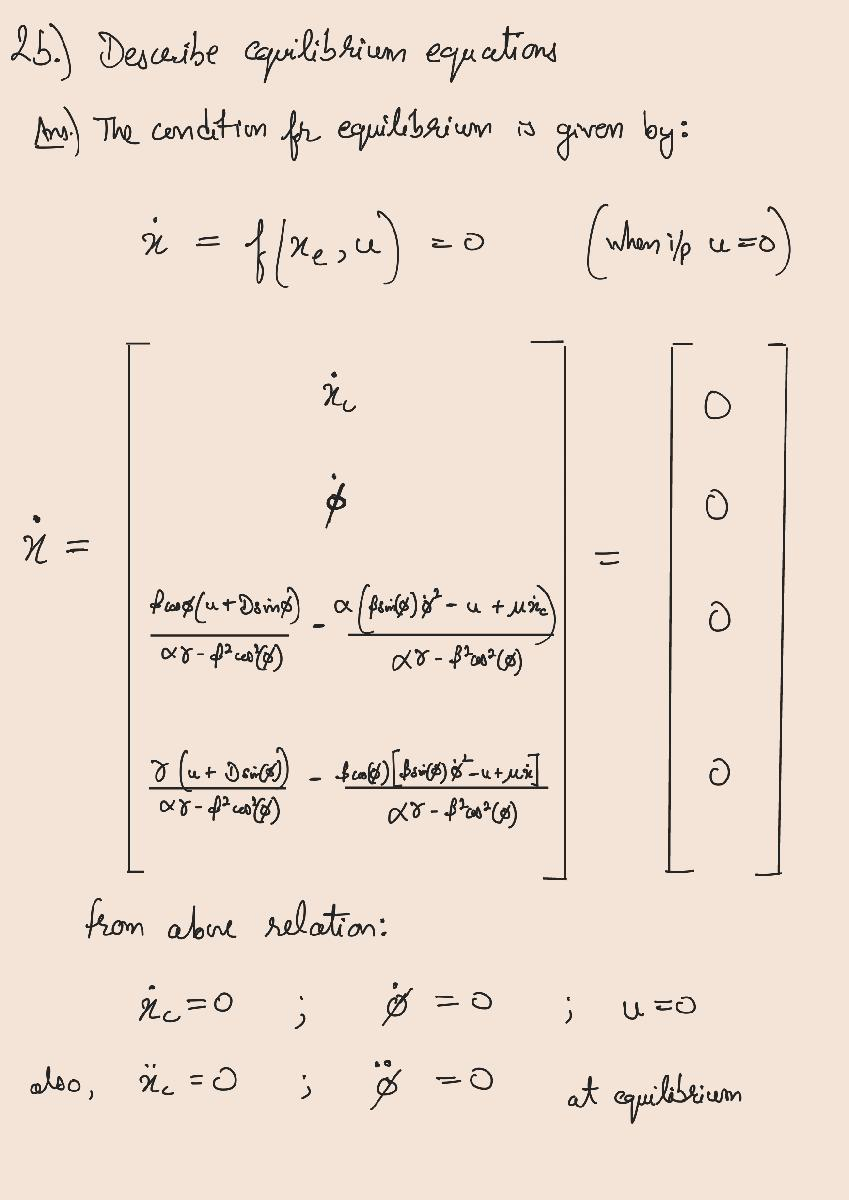

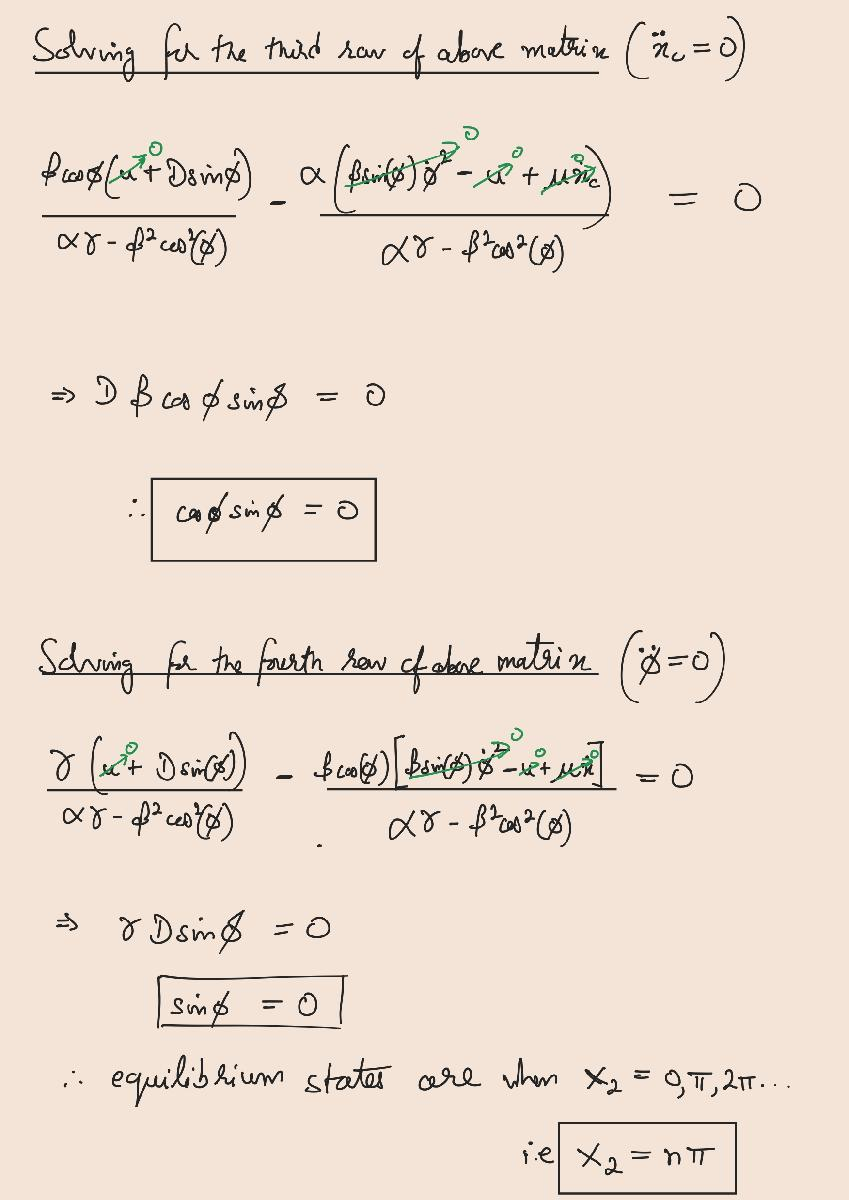

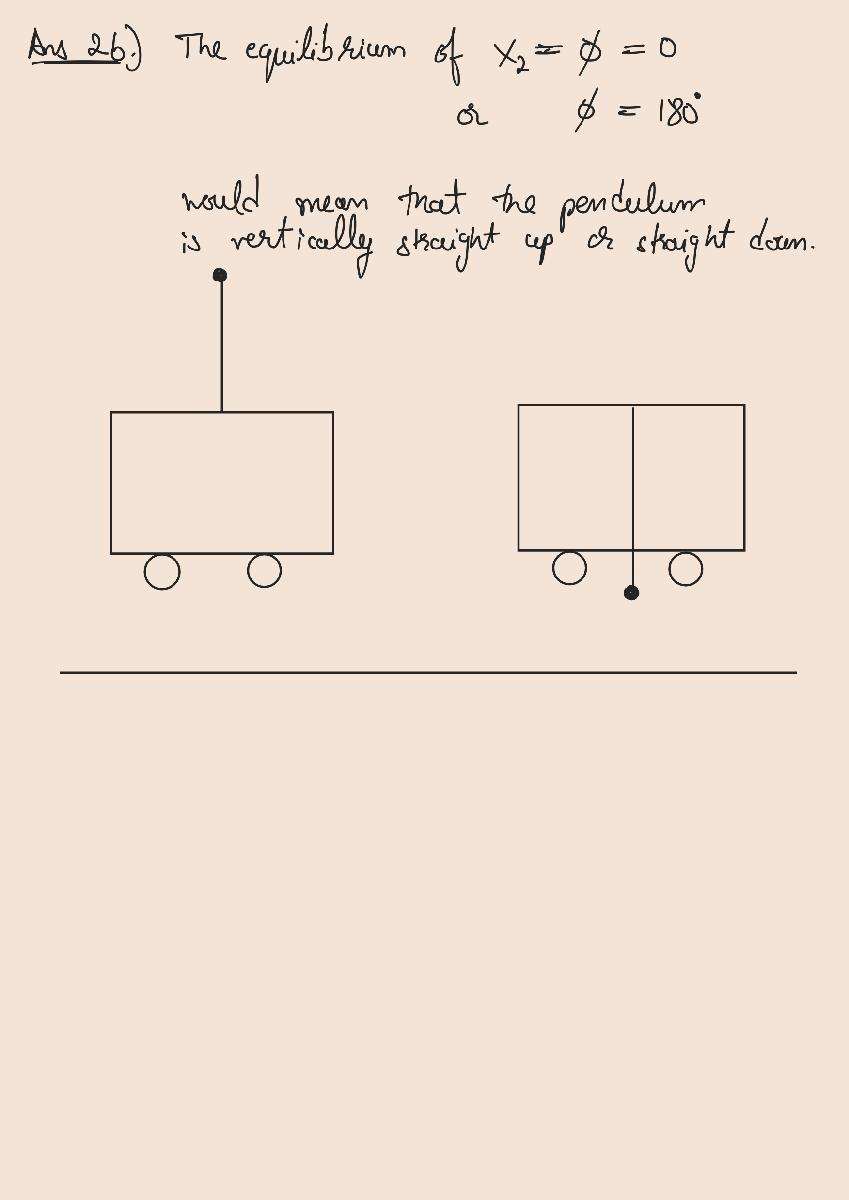

#### 2 c. Compute the eigen values of matrix A which represents the linearized system about the equilibrium point at x = 0

A = [[0,0,1,0];[0,0,0,1];[0,1,-3,0];[0,2,-3,0]];

B = [0;0;1;1];

eig_A = eig(A)

eig_A =          0
   -3.3301
    1.1284
   -0.7984


Since one the eigenvalues of A have a real positive value the system is unstable about the state x = 0

This means that the vertical upright pendulum is not in stable equilibrium

####  **2 d. Finding the optimal feedback control gain **

Q = [[1,0,0,0];[0,5,0,0];[0,0,1,0];[0,0,0,5]];
R = 10;

K = lqr(A, B, Q, R)

K =    -0.3162   10.2723   -6.7857    9.2183


 Using the above feedback control to plot the state of the linearized system

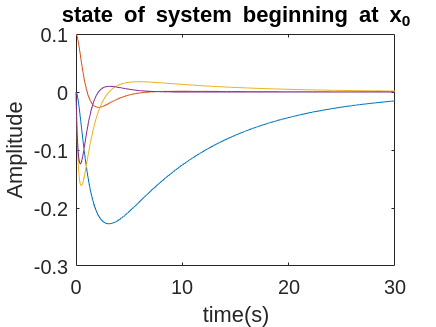

t = 0 : 0.01 : 30 ;

% define three initial state vectors x_0, x_1, and x_2
x_0 = [0; 0.1; 0; 0];
x_1 = [0; 0.5; 0; 0];
x_2 = [0; 1.0886; 0; 0];
x_3 = [0; 1.1; 0; 0];

% plotting the state of system beginning at x_0
[t,x0] = ode45(@(t,x)(A-B*K)*x, t, x_0);
plot(t0,x0)
title('state of system beginning at x_0')
ylabel('Amplitude')
xlabel('time(s)')

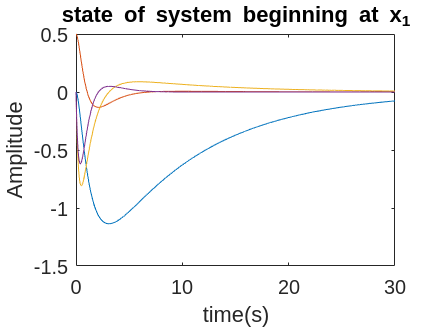


% plotting the state of system beginning at x_1
[t,x1] = ode45(@(t,x)(A-B*K)*x, t, x_1);
plot(t,x1)
title('state of system beginning at x_1')
ylabel('Amplitude')
xlabel('time(s)')

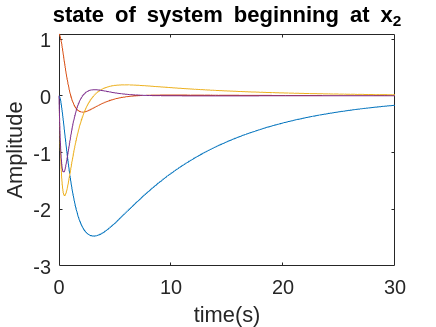


% plotting the state of system beginning at x_2
[t,x2] = ode45(@(t,x)(A-B*K)*x, t, x_2);
plot(t,x2)
title('state of system beginning at x_2')
ylabel('Amplitude')
xlabel('time(s)')

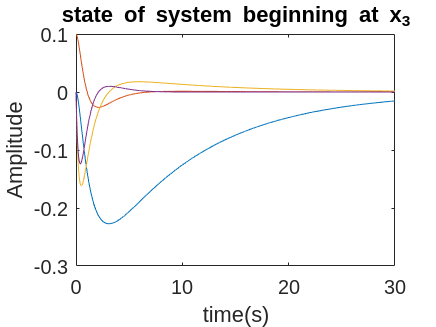


% plotting the state of system beginning at x_0
[t,x3] = ode45(@(t,x)(A-B*K)*x, t, x_3);
plot(t,x0)
title('state of system beginning at x_3')
ylabel('Amplitude')
xlabel('time(s)')

**2 e. Repeat 2 d. using non-linearized state equations**

The non linear system is computed below:

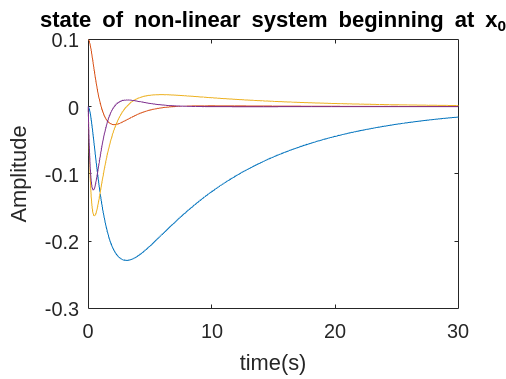

[t,x4] = ode45(@(t,x4)(non_linear_fun(x4, -K*x4)), t, x_0);
plot(t, x4)
title('state of non-linear system beginning at x_0')
ylabel('Amplitude')
xlabel('time(s)')

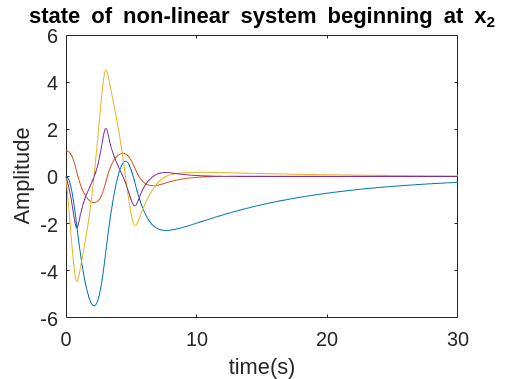


[t,x4] = ode45(@(t,x4)(non_linear_fun(x4, -K*x4)), t, x_2);
plot(t, x4)
title('state of non-linear system beginning at x_2')
ylabel('Amplitude')
xlabel('time(s)')


[t,x4] = ode45(@(t,x4)(non_linear_fun(x4, -K*x4)), t, x_3);

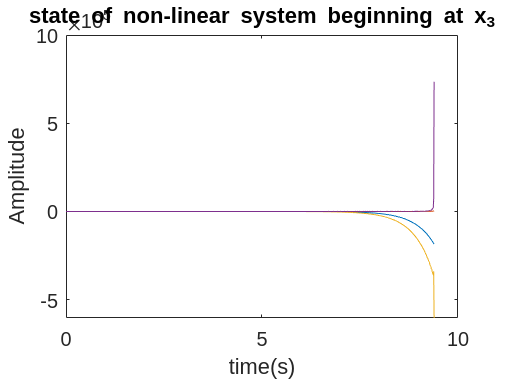

plot(t, x4)
title('state of non-linear system beginning at x_3')
ylabel('Amplitude')
xlabel('time(s)')

The non-linear system is not stable when the initial state vector has a high value of x_c as in the case of x_3 = [0; 1.1; 0; 0]

**2 f. Find the matrix C to sensor measurements in y are in inches ( y = Cx )**

y measures only position therefore should have a dimension of (1,) i.e is a scalar

x = [ x; ϕ; x'; ϕ'] and has shape (4,1)

Therefore C must have shape (1,4)

% Finding C from above equation

% 1 metre = 39.3701 inches, therefore C must be

C = [39.3701, 0, 0, 0]

C =    39.3701         0         0         0


**2 g. Create a tracking controller to specify a desired cart position trajectory**

A tracking controller is represented as:

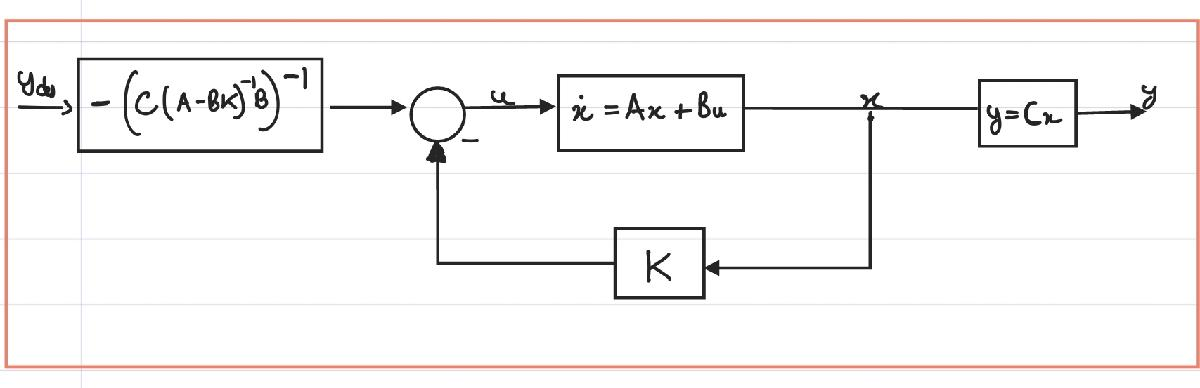

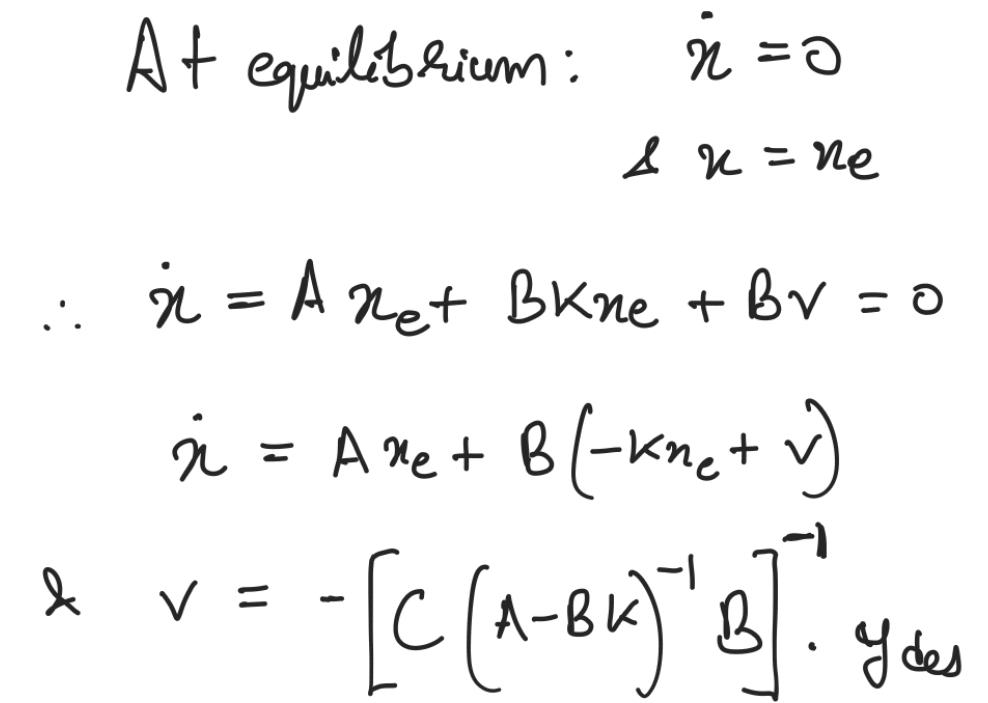

% Defining the specified timesteps and duration
t_5 = 0 : 0.01 : 200;
x_5 = [0; 0; 0; 0];
K % from previous LQR caluculation

K =    -0.3162   10.2723   -6.7857    9.2183


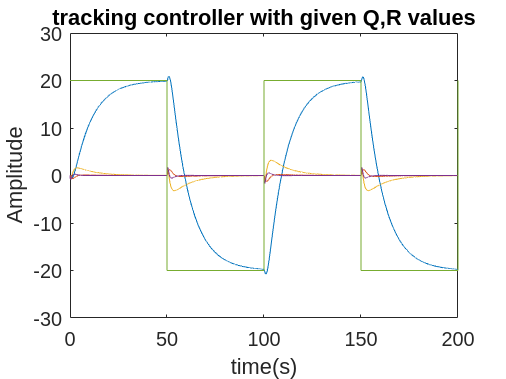


% define parameters for y_des only for plotting
freq=0.01;
offset=0;
amp=20;
duty=50;

% define y_des as a square wave function
y_des = offset+amp*square(2*pi*freq.*t_5,duty);

v = -1 * inv(C*inv((A-B*K))*B);

[t,x5] = ode45(@(t,x5)(tracking_controller(x5, -K*x5, v, t)), t_5, x_5);

% since y_des is in inches and x5 is in metres, we multiply the x5 plot
plot(t, x5*39.3701)
hold on
plot(t_5,y_des)
hold off
title('tracking controller with given Q,R values')
ylabel('Amplitude')
xlabel('time(s)')

**2 f. Improving the Tracking Controller**

The Q and R values can be tuned to track the square wave desired output. It can be improved in the following ways

- Currently the controlloer is reaching the required amplitude very late. Therefore Q can be increased to reduce convergence time

% using t_5 timespan and x_5 initial state specified in 2.d

Q = [[10,0,0,0];[0,5,0,0];[0,0,1,0];[0,0,0,5]];
R = 20;
K = lqr(A, B, Q, R)

K =    -0.7071   11.2732   -7.7079   10.2244


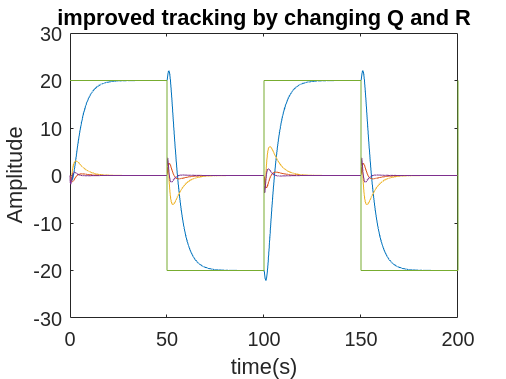


v = -1 * inv(C*inv((A-B*K))*B);

[t,x5] = ode45(@(t,x5)(tracking_controller(x5, -K*x5, v, t)), t_5, x_5);
% since y_des is in inches and x5 is in metres, we multiply the x5 plot
plot(t, x5*39.3701)
hold on
plot(t_5,y_des)
hold off
title('improved tracking by changing Q and R')
ylabel('Amplitude')
xlabel('time(s)')

Helper functions defined for ode45

function x_dot = tracking_controller (x, F, v, t)
xc = x(1);
phi = x(2);
xcdot = x(3);
phidot = x(4);

% constants in the system
gamma = 2;
alpha = 1;
beta = 1;
D = 1;
mu = 3;

% define parameters for y_des
freq=0.01;
offset=0;
amp=20;
duty=50;

% define y_des as a square wave function
y_des = offset+amp*square(2*pi*freq.*t,duty);
u = F + v*y_des;

divisor = ((gamma*alpha) - (beta*beta*cos(phi)*cos(phi)))^(-1);

x_dot = [xcdot;
        phidot;
        divisor*((u*alpha) - (beta*phidot*phidot*sin(phi)*alpha) - (alpha*mu*xcdot) + (beta*D*sin(phi)*cos(phi)));
        divisor*((u*beta*cos(phi)) - (beta*beta*phidot*phidot*sin(phi)*cos(phi)) - (beta*cos(phi)*mu*xcdot) + (gamma*D*sin(phi)))];


% divisor_1 = alpha / ((gamma*alpha) - (beta*beta*cos(phi)*cos(phi)));
% divisor_2 = (beta*cos(phi)) / ((gamma*alpha) - (beta*beta*cos(phi)*cos(phi)));

% x_dot = [xcdot;
%        phidot;
%        divisor_1*(u - (beta*phidot*phidot*sin(phi)) - (mu*xcdot) + ((beta*D*cos(phi)*sin(phi))/alpha));
%        divisor_2*(u - (beta*phidot*phidot*sin(phi)) - (mu*xcdot) + ((gamma*D*sin(phi)) / (beta*cos(phi))))];

end

function x_dot = non_linear_fun (x, u)
xc = x(1);
phi = x(2);
xcdot = x(3);
phidot = x(4);

% constants in the system
gamma = 2;
alpha = 1;
beta = 1;
D = 1;
mu = 3;

divisor = ((gamma*alpha) - (beta*beta*cos(phi)*cos(phi)))^(-1);

x_dot = [xcdot;
        phidot;
        divisor*((u*alpha) - (beta*phidot*phidot*sin(phi)*alpha) - (alpha*mu*xcdot) + (beta*D*sin(phi)*cos(phi)));
        divisor*((u*beta*cos(phi)) - (beta*beta*phidot*phidot*sin(phi)*cos(phi)) - (beta*cos(phi)*mu*xcdot) + (gamma*D*sin(phi)))];


% divisor_1 = alpha / ((gamma*alpha) - (beta*beta*cos(phi)*cos(phi)));
% divisor_2 = (beta*cos(phi)) / ((gamma*alpha) - (beta*beta*cos(phi)*cos(phi)));

% x_dot = [xcdot;
%        phidot;
%        divisor_1*(u - (beta*phidot*phidot*sin(phi)) - (mu*xcdot) + ((beta*D*cos(phi)*sin(phi))/alpha));
%        divisor_2*(u - (beta*phidot*phidot*sin(phi)) - (mu*xcdot) + ((gamma*D*sin(phi)) / (beta*cos(phi))))];

end